clear; clc;
mFile = 'mask\mask2m_16_16.mat';
load(mFile); % mask2m 304x304x361

% Get the dimensions of the data


[h, w, c] = size(mask2m);

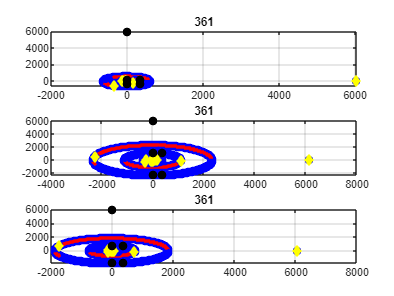


% Plot the FFT data and mark the highest frequency points
figure(4); clf; m = 0;
for k = [1 3190 9570]
    m = m + 1;
    subplot(3, 1, m)
    
    % Reshape the data into a 2D matrix
    x = reshape(mask2m, h * w, c);
    Ns = (c + 1) / 2;
    y = x(k, :);
    
    for cN = 0:c
        yy = circshift(y, cN);
        fyy = fft(yy);
        fyy(1);
        plot(fyy(1:Ns), 'ob', 'MarkerFaceColor', 'b');
        hold on;
        plot(fyy(Ns + 1:end), '.r', 'markersize', 8);
        set(gca, 'xscale', 'lin');
        title(num2str(cN));
        grid on;
    end
    
    cN = 0;
    yy = circshift(y, cN);
    fyy = fft(yy);
    plot(fyy(1:Ns), 'dy', 'MarkerFaceColor', 'y');
    
    % Calculate and plot the top frequency points in the FFT
    [~, idx] = sort(abs(fyy), 'descend');
    top_freq_points = fyy(idx(1:5)); % Take the top 5 highest frequency points
    top_freq_indices = idx(1:5);
    hold on;
    plot(top_freq_indices, top_freq_points, 'ko', 'MarkerFaceColor', 'k');
end

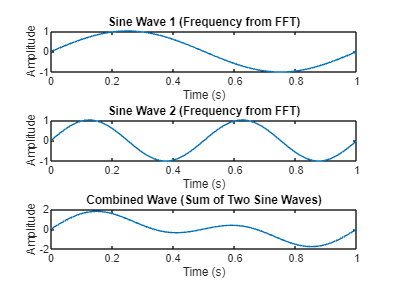


% Take a sine wave and two sine waves from the FFT data and plot them
% Define parameters
Fs = 1000;            % Sampling frequency
T = 1/Fs;             % Sampling period
L = 1000;             % Length of signal
t = (0:L-1)*T;        % Time vector

% Generate sine waves from FFT data
sine_wave_1 = sin(2*pi*top_freq_indices(1)*t);
sine_wave_2 = sin(2*pi*top_freq_indices(2)*t);

% Plot the sine waves
figure;
subplot(3, 1, 1);
plot(t, sine_wave_1);
title('Sine Wave 1 (Frequency from FFT)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3, 1, 2);
plot(t, sine_wave_2);
title('Sine Wave 2 (Frequency from FFT)');
xlabel('Time (s)');
ylabel('Amplitude');

% Generate and plot the sum of two sine waves
combined_wave = sine_wave_1 + sine_wave_2;
subplot(3, 1, 3);
plot(t, combined_wave);
title('Combined Wave (Sum of Two Sine Waves)');
xlabel('Time (s)');
ylabel('Amplitude');


% Remark:
% The first set of plots shows the FFT data with the highest frequency points marked.
% The second set of plots shows sine waves generated using the frequencies obtained from the FFT data.
% The third plot shows the sum of two sine waves. 